# MIMO Simulation at 28 GHz in an Indoor Environment

### Ozlem Yildiz    zy2043    

### Ufuk Usubutun    uu2001

## Loading Data

load roomPathData.mat

rxPos = pathData.rxPos;
nrxPos = size(rxPos, 1);

txPos = pathData.txPos; 

npaths = pathData.npaths;
linkState = pathData.linkState;


% RX position selection random
i_rx = 15;% randi(nrxPos);

fc = pathData.fc;

%Angels

aoaAz = pathData.aoaAz(i_rx, :)';
aoaEl = pathData.aoaEl(i_rx, :)';
aodAz = pathData.aodAz(i_rx, :)';
aodEl = pathData.aodEl(i_rx, :)';

pl = pathData.pl(i_rx, :);
dly = pathData.dly(i_rx,:)';
gain = pathData.gain(i_rx,:)';

posStep = pathData.posStep;

## Data Demonstration

Parameters are from 'indoorDataDemo' 

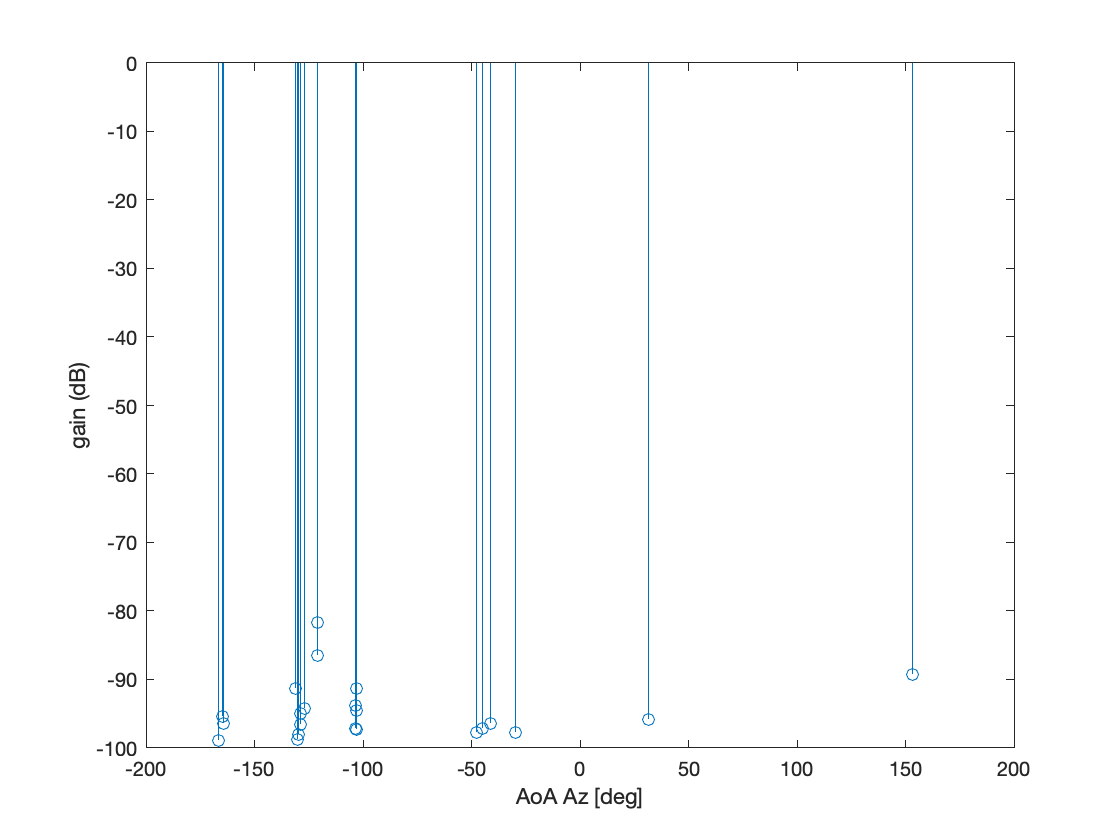

txPow = 0; %dB
% nf = 7;      % Noise figure
% bw = 400e6;  % Bandwidth
Ekt = -174;  % Thermal noise

%??
gain = txPow - pl';%  - nf - Ekt - 10*log10(bw);

figure;
stem(aoaAz, gain);
ylabel('gain (dB)');
xlabel('AoA Az [deg]');

## Antenna Array

Demo 'mimoCapacity' has been taken into consideration. High-dimensional antenna arrays are used because of the carrier frequency. 

- TX: 4x4 URA 

- RX:  8x1 ULA

 The paths are angularly clustered so the channel has lower rank. 

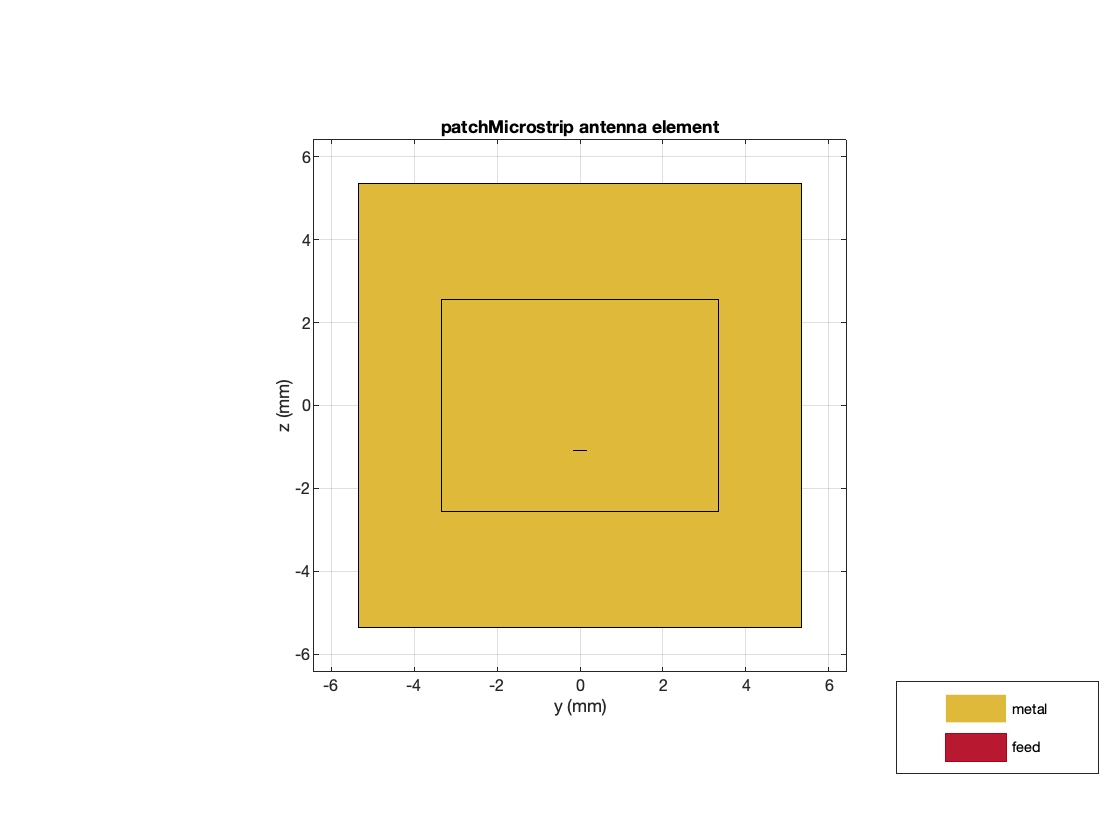

%elem = design(fractalCarpet, fc);
elem = design(patchMicrostrip, fc);
elem.Tilt = 90;
elem.TiltAxis = [0 1 0];
elem.show();
view(90,0)

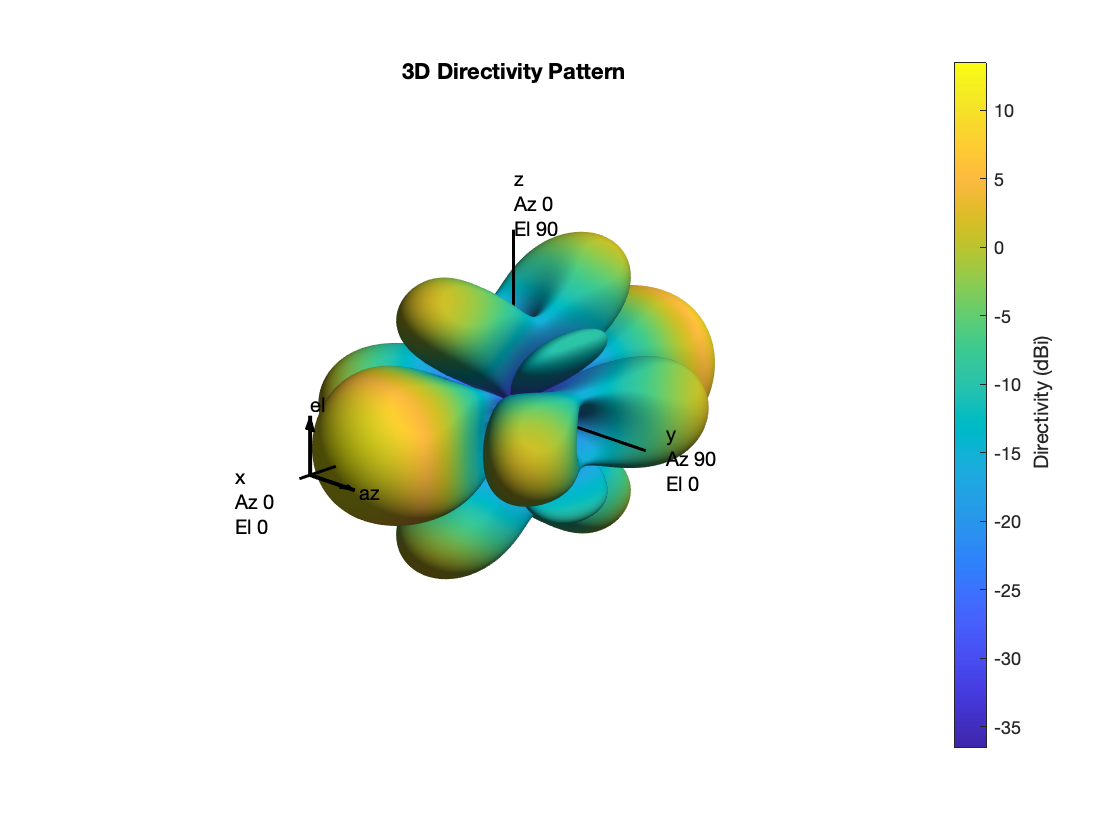

lambda = physconst('LightSpeed')/fc;

% Array parameters
dsep = 0.5*lambda;   % element spacing
nantRx = 8;          % Number of RX elements
nantTx = [4,4];      % Number of TX elements


arrRx = phased.ULA(nantRx,dsep,'ArrayAxis', 'x');
arrTx = phased.URA(nantTx,dsep,'ArrayNormal','x');

arrTx.pattern(fc)

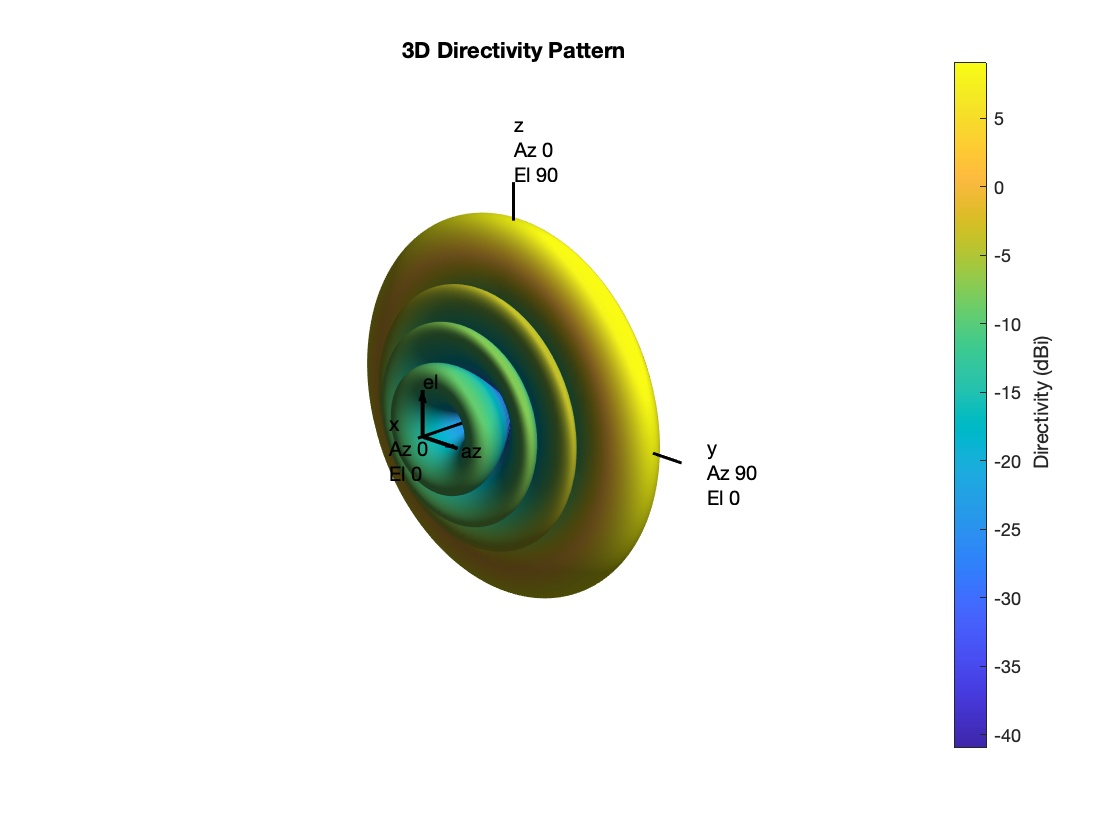

arrRx.pattern(fc)

## Array Orientation

arrPlatformTx = ArrayPlatform('elem', elem, 'arr', arrTx, 'fc', fc);
arrPlatformTx.computeNormMatrix();

arrPlatformRx =  ArrayPlatform('elem', elem, 'arr', arrRx, 'fc', fc);
arrPlatformRx.computeNormMatrix();

Following labBF: 

[svTx, elemGainTx] = arrPlatformTx.step(aodAz, aodEl, true);
[svRx, elemGainRx] = arrPlatformRx.step(aoaAz, aoaEl, true);

Gain total:

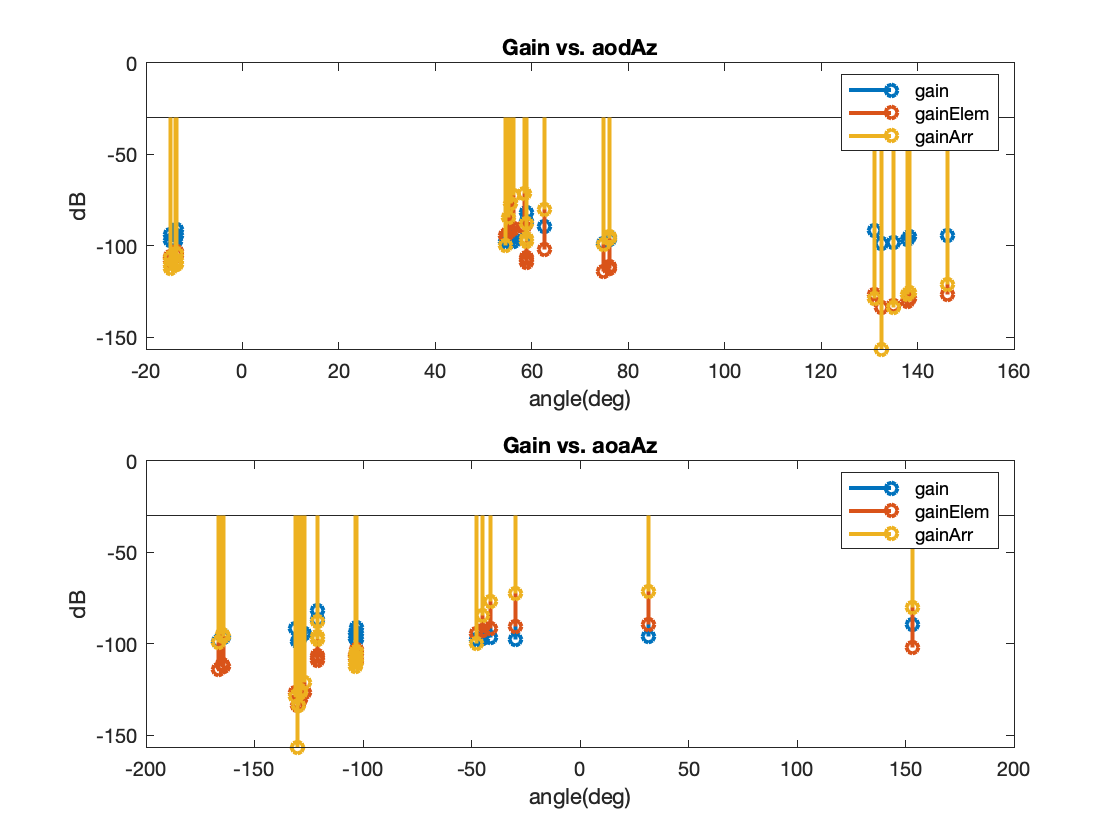

gainElem = elemGainTx + elemGainRx + gain;

[~,index] = max(gainElem);

wtx = conj(svTx(:,index)); 
wtx = wtx/ norm(wtx);
wrx = conj(svRx(:,index)); 
wrx = wrx/ norm(wrx);
arrGainTx = mag2db(abs(wtx.'*svTx))';
arrGainRx = mag2db(abs(wrx.'*svRx))';
gainArr = gain + arrGainTx + arrGainRx;


figure;

subplot(2,1,1)
stem(aodAz, gain, 'BaseValue', -30, 'LineWidth',2)
hold on
stem(aodAz, gainElem, 'BaseValue', -30, 'LineWidth',2)
hold on
stem(aodAz, gainArr, 'BaseValue', -30, 'LineWidth',2)
title('Gain vs. aodAz')
xlabel('angle(deg)')
ylabel('dB')
legend('gain', 'gainElem', 'gainArr')

subplot(2,1,2)
stem(aoaAz, gain, 'BaseValue', -30, 'LineWidth',2)
hold on 
stem(aoaAz, gainElem, 'BaseValue', -30, 'LineWidth',2)
hold on
stem(aoaAz, gainArr, 'BaseValue', -30, 'LineWidth',2)
title('Gain vs. aoaAz')
xlabel('angle(deg)')
ylabel('dB')
legend('gain', 'gainElem', 'gainArr')

## Frequency Domain Channel

The following part is followed from Beamforming lab

SubcarrierSpacing = 120;    % SCS in kHZ
NRB = 61;  % number of resource blocks
nscPerRB = 12;  % number of sub-carriers per RB

bw = SubcarrierSpacing*1e3*NRB*nscPerRB;

carrierConfig = nrCarrierConfig(...
    'NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing);
waveformConfig = nrOFDMInfo(carrierConfig);

Channel for one slot:

Enoise = Ekt + 10*log10(bw);%  % noise energy dB
fdchan = FDMIMOChan(carrierConfig, 'txArrPlatform', arrPlatformTx, 'rxArrPlatform', arrPlatformRx, ...
    'aoaAz', aoaAz, 'aodAz', aodAz, 'aoaEl', aoaEl, 'aodEl', aodEl,  ...
    'gain', gain, 'dly', dly, 'fc', fc, 'Enoise', Enoise);
frameNum = 0;
slotNum = 0;
[chanGrid, noiseVar] = fdchan.step(frameNum, slotNum);




Let's look at the eigenvalue decomposition of the channel averaged over time and frequency to look at availability of virtual paths, i.e. diversity (H'*H = VDV')

temp = pagemtimes(pagectranspose(chanGrid),chanGrid);
temp = mean(temp, [3 4]);
[V,D] = eig(temp);

% Capacity
C = log2(det( eye(size(temp)) + db2pow(txPow)*temp/noiseVar )  )

C = 30.9896 - 0.0000i

## Transmitter

Precoder



numVirtual = 5;

Precoder = V(:,end-numVirtual+1:end);


Let's have the same approach we had at the final exam and define a new channel A to include precoding and the actual channel

A = pagemtimes(chanGrid,Precoder);


Demonstration:

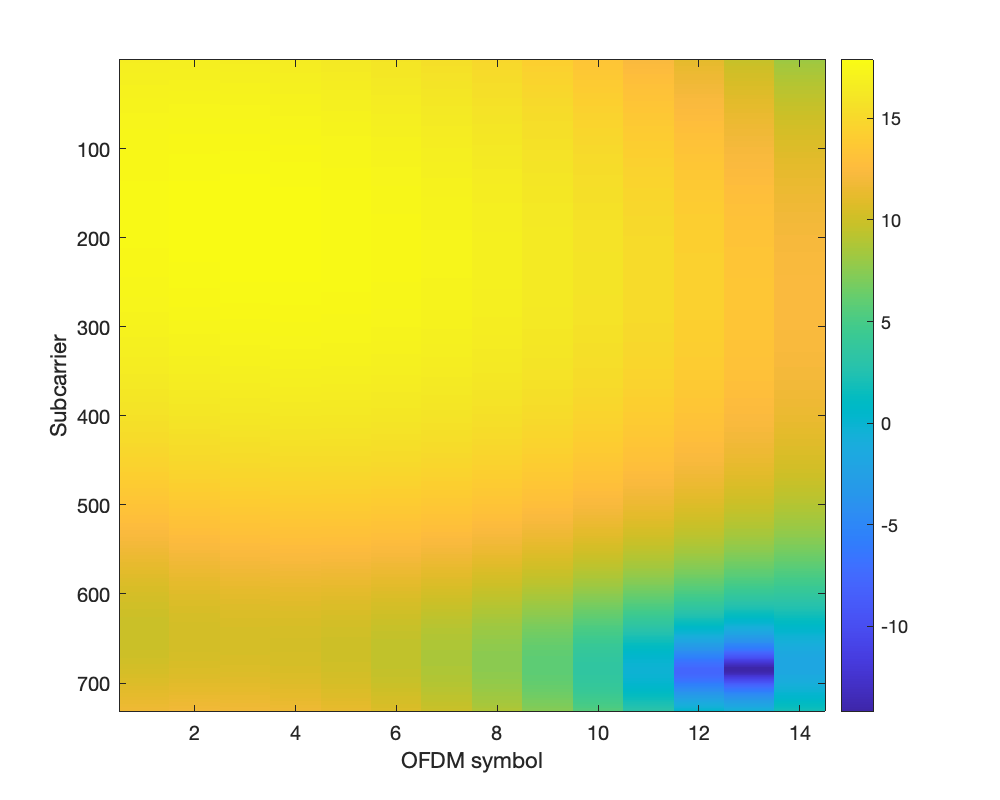

clf;
set(gcf,'Position', [0,0,500,400]);
chanGainSing = squeeze( abs(chanGrid(3,4,:,:)).^2 );
snrSing = 10*log10(chanGainSing / noiseVar);
imagesc(snrSing);
colorbar();
xlabel('OFDM symbol');
ylabel('Subcarrier');

Now for the transmitter we create a pdfschConfig as usual, but we now have NumLayers = nstream. So we create a tx object.

mcsInd = 12;

Modulation = '16QAM';
targetCodeRate = 434/1024;

pdschConfig = nrPDSCHConfig(...
    'Modulation', Modulation, ...
    'PRBSet', (0:NRB-1), ...
    'SymbolAllocation', [1, waveformConfig.SymbolsPerSlot-1], ...
    'PTRS', nrPDSCHPTRSConfig(),...
    'NumLayers', 1);
  %  'EnablePTRS', 1,...
tx = NRgNBTxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate);

Now we create a txGrid

txGrid = tx.step(numVirtual); 
figure(2)
imagesc(real(squeeze(txGrid(1,1,:,:))))
colorbar

We precode the txGrid by the precoder calculated above

txGridPrecoded = pagemtimes(Precoder,txGrid);

Now we pass precoded grid through the chanGrid 

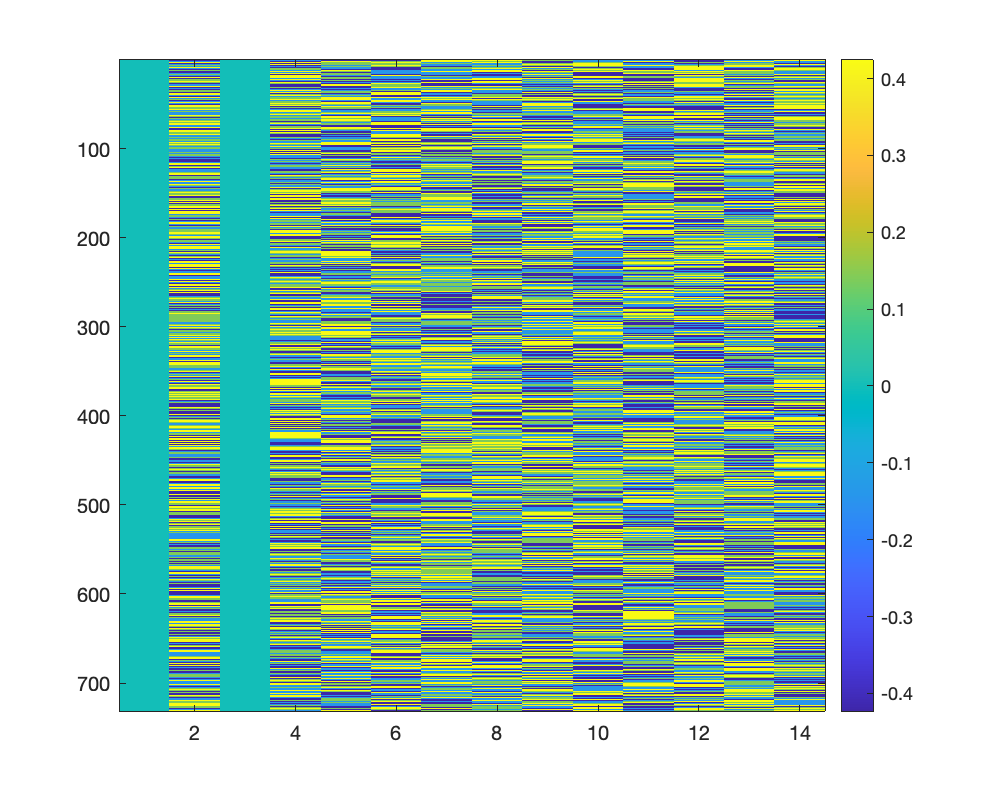

rxgrid = pagemtimes(chanGrid,txGridPrecoded);
rxgrid = rxgrid + sqrt(noiseVar/2).*( randn(size(rxgrid)) + 1i.*randn(size(rxgrid))); 

## Receiver

Now we have to perform LMMSE before decoding

alpha = db2pow(txPow)/(noiseVar*prod(nantTx));

% implemented by following LMMSE decoder from slide 45 of MIMO Unit
temp = pagemtimes(pagectranspose(A),A);
temp = alpha*temp +  repmat( eye(size(temp,[1,2])), [1, 1, size(temp, [3 4]) ]) ;

F = zeros(size(temp));
for i=1:size(temp,3)
    for j=1:size(temp,4)
        F(:,:,i,j) = temp(:,:,i,j)^(-1);
    end
end
F = alpha*pagemtimes(F, pagectranspose(A));


% 
%%%%%%%Heq = pagemtimes(F,G); %Equalized channel, it should be close to identity matrix at high SNR
% 
rxGridEq = squeeze(pagemtimes(F,rxgrid)); %Equalizing received signal
% % 
% % %Test: Since we don't have noise rxGridEq and txGrid should be same
% figure(3)
% imagesc(real(squeeze(rxGridEq(1,:,:)))-squeeze(real(txGrid(1,1,:,:))))
% colorbar

order of 10^-16 for the difference so we did LMMSE correctly.

## Demodulation

**TODO :First we calculate LMMSE noise variances across each stream**

% we can use the same temp as above which conatins (A'*A)
% temp = pagemtimes(pagectranspose(G),G);
% temp = alpha*temp +  repmat( eye(size(temp,[1,2])), [1, 1, size(temp, [3 4]) ]) ;

% implemented by following SINR per channel from slide 48 of MIMO Unit

QLMMSE = zeros(size(temp));
for i=1:size(temp,3)
    for j=1:size(temp,4)
        QLMMSE(:,:,i,j) = temp(:,:,i,j)^(-1);
    end
end


SNR of Virtual Channels

snrLin = real(1./diag(mean(QLMMSE,[3 4])) - 1);
snrdB = pow2db(snrLin)
noiseVarStreams = sqrt(1./snrLin);

Then we demodulate equalized signal

rx = NRUERxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate);
rx.step(rxGridEq, Heq, noiseVarStreams,numVirtual); %Demodulation

snrdB =   -13.2974
  -13.7701
   11.5503
   12.5403
   18.8898


%Test
rxBits = rx.rxBits;
%CHANGE HERE FOR BETTER PERFORMANCE
txBits = [];
for i=1:numVirtual
    txBits = [txBits ;tx.txBits{i}];
end

CorrectBits = length(find(rxBits == txBits));
TotalBits = length(txBits);


% 
fprintf('%d,%d',CorrectBits,TotalBits)

OFDM Beamforming as like Lab8

% nsc = size(chanGrid,3);
% nsym = size(chanGrid,4);
% snrInst = zeros(nsc,nsym);
% for n = 1:nsc
%     for t = 1:nsym

62334,74280

%         chani = squeeze(chanGrid(:,:,n,t));
%         [wrxi,si,wtxi] = svds(chani, 1);
%         
%         snrInst(n, t) = pow2db(si^2/noiseVar);
%     end
% end
% 
% imagesc(snrInst);
% colorbar();
% xlabel('OFDM symbol');
% ylabel('Subcarrier');